
clc;
clear;
close all;

%% =========================================
% RUTA DE LA CARPETA
% ==========================================

carpeta = "C:\Users\User\Desktop\Universidad\9. Noveno Semestre\Diseno Mecatronico\ControlMotores\Caracterizacion De Motores\datos_caracterizacion";

%% =========================================
% NOMBRES DE LOS ARCHIVOS
% ==========================================

prefijo = "20261109_171147_ambos_adelante_atras_pwm_30";

archivoPWM = fullfile(carpeta, prefijo + "_PWM.csv");
archivoIzq = fullfile(carpeta, prefijo + "_RPM_IZQUIERDO.csv");
archivoDer = fullfile(carpeta, prefijo + "_RPM_DERECHO.csv");

%% =========================================
% VERIFICAR ARCHIVOS
% ==========================================

if ~isfile(archivoPWM)
    error("No se encuentra el archivo PWM.");
end

if ~isfile(archivoIzq)
    error("No se encuentra el archivo RPM izquierdo.");
end

if ~isfile(archivoDer)
    error("No se encuentra el archivo RPM derecho.");
end

%% =========================================
% LEER LOS TRES CSV
% ==========================================

datosPWM = readtable(archivoPWM);
datosRPMIzq = readtable(archivoIzq);
datosRPMDer = readtable(archivoDer);

%% =========================================
% EXTRAER VARIABLES
% ==========================================

% Tiempos de cada archivo
tiempoPWM = datosPWM.tiempo_s;
tiempoRPMIzq = datosRPMIzq.tiempo_s;
tiempoRPMDer = datosRPMDer.tiempo_s;

% PWM aplicado a cada motor
% La prueba utiliza la misma orden para ambos motores
pwmIzq = datosPWM.PWM;
pwmDer = datosPWM.PWM;

% RPM medidas por cada encoder
rpmIzq = datosRPMIzq.RPM;
rpmDer = datosRPMDer.RPM;

%% =========================================
% VERIFICAR VARIABLES EN WORKSPACE
% ==========================================

disp("Datos cargados correctamente.");

Datos cargados correctamente.



whos pwmIzq pwmDer rpmIzq rpmDer

  Name          Size            Bytes  Class     Attributes

  pwmDer      185x1              1480  double              
  pwmIzq      185x1              1480  double              
  rpmDer      185x1              1480  double              
  rpmIzq      185x1              1480  double              



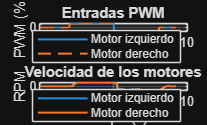


%% =========================================
% GRAFICAR PWM Y RPM
% ==========================================

figure;

subplot(2,1,1);
plot(tiempoPWM, pwmIzq, 'LineWidth', 1.2);
hold on;
plot(tiempoPWM, pwmDer, '--', 'LineWidth', 1.2);
grid on;
ylabel('PWM (%)');
legend('Motor izquierdo', 'Motor derecho');
title('Entradas PWM');

subplot(2,1,2);
plot(tiempoRPMIzq, rpmIzq, 'LineWidth', 1.2);
hold on;
plot(tiempoRPMDer, rpmDer, 'LineWidth', 1.2);
grid on;
xlabel('Tiempo (s)');
ylabel('RPM');
legend('Motor izquierdo', 'Motor derecho');
title('Velocidad de los motores');